% Airfoil Geometry
airfoil = loadAirfoil();

'naca5gen' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\satur\OneDrive - University of Kansas\MATLAB\AE 546

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in Lab_1_altered_data>loadAirfoil (line 100)
    airfoil = naca5gen(iaf);

[DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c] = possitionDeltas(airfoil)

DxLower_c =     0.0074
    0.0150
    0.0217
    0.0279
    0.0340
    0.0406
    0.0503
    0.0544
    0.0587
    0.0619


DxUpper_c =     0.0043
    0.0128
    0.0211
    0.0290
    0.0364
    0.0432
    0.0493
    0.0545
    0.0588
    0.0621


DyLower_c =    -0.0096
   -0.0069
   -0.0051
   -0.0043
   -0.0042
   -0.0046
   -0.0046
   -0.0035
   -0.0019
   -0.0003


DyUpper_c =    -0.0007
   -0.0021
   -0.0034
   -0.0046
   -0.0055
   -0.0063
   -0.0069
   -0.0072
   -0.0073
   -0.0071


xLower_c =     0.0037
    0.0149
    0.0332
    0.0580
    0.0890
    0.1263
    0.1717
    0.2241
    0.2806
    0.3409


xUpper_c =     0.9979
    0.9893
    0.9724
    0.9473
    0.9146
    0.8747
    0.8285
    0.7766
    0.7199
    0.6595


yLower_c =    -0.0048
   -0.0130
   -0.0190
   -0.0237
   -0.0280
   -0.0324
   -0.0370
   -0.0411
   -0.0438
   -0.0449


yUpper_c =     0.0004
    0.0018
    0.0045
    0.0085
    0.0136
    0.0195
    0.0261
    0.0331
    0.0404
    0.0476



% Experimental Data
dataFileName = "Lab1_Data.xlsx";
%dataFileName = "Lab1_Data_raw.xlsx";

opts = detectImportOptions(dataFileName);
dataMatrix = readmatrix(dataFileName, "Range", "A1:G51"); % Data in A2 trhough G51
% first row is angle of attack second row is static head thid row is total  
% head subsiquent rows are local head measuremnts
AoAs = dataMatrix(1,:);
staticHeads = dataMatrix(2,:);
totalHeads = dataMatrix(3,:);
localHeads = dataMatrix(4:end,:); % I belice all is well with data imports

% initialize constants
mu = 1.78E-5; % kg/(m*s) viscosity of air
rhoAir = 1.225; % kg/m^3 density of air
rhoLiquid = 836; % kg/m^3 density of manomiter liquid
g = 9.81; % m/s acceleration due to gravity
c = .195; % m cord length

%variabel for data to be saved in
countOfAoAs = length(AoAs);
countOPoints = length(localHeads);
Res = zeros(0, countOfAoAs);
Cls = zeros(0, countOfAoAs);
Cds = zeros(0, countOfAoAs);
Cmc_4s = zeros(0, countOfAoAs);
CpUppers  = zeros(countOPoints / 2, countOfAoAs);
CpLowers  = zeros(countOPoints / 2, countOfAoAs);


%TODO: repeat for each AOA
i=1 % make i for loop itteration var

i = 1

for i = 1:countOfAoAs
    
    alpha = AoAs(i)
    hs = staticHeads(i);
    ht = totalHeads(i);
    hlocal = localHeads(:,i);
    %[CpUpper, CpLower] = getCps(hs, ht, hlocal)
    [CpUppers(:,i), CpLowers(:,i)] = getCps(hs, ht, hlocal)
    
    % calculate at one AoA; local coeffs: cp cl cd cm,c/4
    [Cls(i), Cds(i), Cmc_4s(i)] = getCoeffs(alpha, CpUppers(:,i), CpLowers(:,i), DxLower_c, DxUpper_c, DyLower_c, DyUpper_c,xLower_c, xUpper_c, yLower_c, yUpper_c)
    
end

alpha = -8

CpUppers =     0.4630         0         0         0         0         0         0
    0.8148         0         0         0         0         0         0
    0.5556         0         0         0         0         0         0
    0.3657         0         0         0         0         0         0
    0.1759         0         0         0         0         0         0
    0.0417         0         0         0         0         0         0
    0.0417         0         0         0         0         0         0
   -0.0926         0         0         0         0         0         0
   -0.1389         0         0         0         0         0         0
   -0.1389         0         0         0         0         0         0


CpLowers =    -0.2963         0         0         0         0         0         0
   -0.3148         0         0         0         0         0         0
   -0.2963         0         0         0         0         0         0
    0.2593         0         0         0         0         0         0
    0.4259         0         0         0         0         0         0
    0.5926         0         0         0         0         0         0
    0.4722         0         0         0         0         0         0
    0.6528         0         0         0         0         0         0
    0.8333         0         0         0         0         0         0
    0.1852         0         0         0         0         0         0


Cls = -0.3242

Cds = 0.0906

Cmc_4s = 0.2612

alpha = -4

CpUppers =     0.4630    0.4762         0         0         0         0         0
    0.8148    0.7905         0         0         0         0         0
    0.5556    0.4762         0         0         0         0         0
    0.3657    0.2667         0         0         0         0         0
    0.1759    0.0571         0         0         0         0         0
    0.0417   -0.0714         0         0         0         0         0
    0.0417   -0.0714         0         0         0         0         0
   -0.0926   -0.2000         0         0         0         0         0
   -0.1389   -0.2190         0         0         0         0         0
   -0.1389   -0.2000         0         0         0         0         0


CpLowers =    -0.2963   -0.0476         0         0         0         0         0
   -0.3148   -0.0952         0         0         0         0         0
   -0.2963   -0.0952         0         0         0         0         0
    0.2593    0.2952         0         0         0         0         0
    0.4259    0.4333         0         0         0         0         0
    0.5926    0.5714         0         0         0         0         0
    0.4722    0.4762         0         0         0         0         0
    0.6528    0.6810         0         0         0         0         0
    0.8333    0.8857         0         0         0         0         0
    0.1852    0.1524         0         0         0         0         0


Cls =    -0.3242   -0.2042


Cds =     0.0906    0.0758


Cmc_4s =     0.2612    0.2369


alpha = 0

CpUppers =     0.4630    0.4762    0.4571         0         0         0         0
    0.8148    0.7905    0.5238         0         0         0         0
    0.5556    0.4762    0.1619         0         0         0         0
    0.3657    0.2667   -0.0476         0         0         0         0
    0.1759    0.0571   -0.2571         0         0         0         0
    0.0417   -0.0714   -0.3476         0         0         0         0
    0.0417   -0.0714   -0.3476         0         0         0         0
   -0.0926   -0.2000   -0.4381         0         0         0         0
   -0.1389   -0.2190   -0.4190         0         0         0         0
   -0.1389   -0.2000   -0.3524         0         0         0         0


CpLowers =    -0.2963   -0.0476   -0.0286         0         0         0         0
   -0.3148   -0.0952   -0.0667         0         0         0         0
   -0.2963   -0.0952   -0.0667         0         0         0         0
    0.2593    0.2952    0.2857         0         0         0         0
    0.4259    0.4333    0.4286         0         0         0         0
    0.5926    0.5714    0.5714         0         0         0         0
    0.4722    0.4762    0.4762         0         0         0         0
    0.6528    0.6810    0.6714         0         0         0         0
    0.8333    0.8857    0.8667         0         0         0         0
    0.1852    0.1524    0.1810         0         0         0         0


Cls =    -0.3242   -0.2042    0.1061


Cds =     0.0906    0.0758    0.0587


Cmc_4s =     0.2612    0.2369    0.0776


alpha = 4

CpUppers =     0.4630    0.4762    0.4571    0.5577         0         0         0
    0.8148    0.7905    0.5238    0.0962         0         0         0
    0.5556    0.4762    0.1619   -0.2500         0         0         0
    0.3657    0.2667   -0.0476   -0.4423         0         0         0
    0.1759    0.0571   -0.2571   -0.6346         0         0         0
    0.0417   -0.0714   -0.3476   -0.7019         0         0         0
    0.0417   -0.0714   -0.3476   -0.7019         0         0         0
   -0.0926   -0.2000   -0.4381   -0.7692         0         0         0
   -0.1389   -0.2190   -0.4190   -0.6250         0         0         0
   -0.1389   -0.2000   -0.3524   -0.5288         0         0         0


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096         0         0         0
   -0.3148   -0.0952   -0.0667   -0.0673         0         0         0
   -0.2963   -0.0952   -0.0667   -0.0769         0         0         0
    0.2593    0.2952    0.2857    0.3077         0         0         0
    0.4259    0.4333    0.4286    0.4471         0         0         0
    0.5926    0.5714    0.5714    0.5865         0         0         0
    0.4722    0.4762    0.4762    0.4808         0         0         0
    0.6528    0.6810    0.6714    0.6731         0         0         0
    0.8333    0.8857    0.8667    0.8654         0         0         0
    0.1852    0.1524    0.1810    0.2115         0         0         0


Cls =    -0.3242   -0.2042    0.1061    0.3833


Cds =     0.0906    0.0758    0.0587    0.0947


Cmc_4s =     0.2612    0.2369    0.0776   -0.0641


alpha = 8

CpUppers =     0.4630    0.4762    0.4571    0.5577    0.4571         0         0
    0.8148    0.7905    0.5238    0.0962   -0.7143         0         0
    0.5556    0.4762    0.1619   -0.2500   -0.9524         0         0
    0.3657    0.2667   -0.0476   -0.4423   -1.0810         0         0
    0.1759    0.0571   -0.2571   -0.6346   -1.2095         0         0
    0.0417   -0.0714   -0.3476   -0.7019   -1.1286         0         0
    0.0417   -0.0714   -0.3476   -0.7019   -1.1286         0         0
   -0.0926   -0.2000   -0.4381   -0.7692   -1.0476         0         0
   -0.1389   -0.2190   -0.4190   -0.6250   -0.9429         0         0
   -0.1389   -0.2000   -0.3524   -0.5288   -0.8095         0         0


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096   -0.0476         0         0
   -0.3148   -0.0952   -0.0667   -0.0673   -0.0476         0         0
   -0.2963   -0.0952   -0.0667   -0.0769   -0.0381         0         0
    0.2593    0.2952    0.2857    0.3077    0.2952         0         0
    0.4259    0.4333    0.4286    0.4471    0.4333         0         0
    0.5926    0.5714    0.5714    0.5865    0.5714         0         0
    0.4722    0.4762    0.4762    0.4808    0.4762         0         0
    0.6528    0.6810    0.6714    0.6731    0.6810         0         0
    0.8333    0.8857    0.8667    0.8654    0.8857         0         0
    0.1852    0.1524    0.1810    0.2115    0.2571         0         0


Cls =    -0.3242   -0.2042    0.1061    0.3833    0.7408


Cds =     0.0906    0.0758    0.0587    0.0947    0.1819


Cmc_4s =     0.2612    0.2369    0.0776   -0.0641   -0.2455


alpha = 12

CpUppers =     0.4630    0.4762    0.4571    0.5577    0.4571    0.4762         0
    0.8148    0.7905    0.5238    0.0962   -0.7143   -2.1143         0
    0.5556    0.4762    0.1619   -0.2500   -0.9524   -2.0476         0
    0.3657    0.2667   -0.0476   -0.4423   -1.0810   -2.0476         0
    0.1759    0.0571   -0.2571   -0.6346   -1.2095   -2.0476         0
    0.0417   -0.0714   -0.3476   -0.7019   -1.1286   -1.8333         0
    0.0417   -0.0714   -0.3476   -0.7019   -1.1286   -1.8333         0
   -0.0926   -0.2000   -0.4381   -0.7692   -1.0476   -1.6190         0
   -0.1389   -0.2190   -0.4190   -0.6250   -0.9429   -1.1905         0
   -0.1389   -0.2000   -0.3524   -0.5288   -0.8095   -1.0000         0


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096   -0.0476   -0.0095         0
   -0.3148   -0.0952   -0.0667   -0.0673   -0.0476   -0.0190         0
   -0.2963   -0.0952   -0.0667   -0.0769   -0.0381         0         0
    0.2593    0.2952    0.2857    0.3077    0.2952    0.3333         0
    0.4259    0.4333    0.4286    0.4471    0.4333    0.4905         0
    0.5926    0.5714    0.5714    0.5865    0.5714    0.6476         0
    0.4722    0.4762    0.4762    0.4808    0.4762    0.5048         0
    0.6528    0.6810    0.6714    0.6731    0.6810    0.7048         0
    0.8333    0.8857    0.8667    0.8654    0.8857    0.9048         0
    0.1852    0.1524    0.1810    0.2115    0.2571    0.2952         0


Cls =    -0.3242   -0.2042    0.1061    0.3833    0.7408    1.1896


Cds =     0.0906    0.0758    0.0587    0.0947    0.1819    0.3552


Cmc_4s =     0.2612    0.2369    0.0776   -0.0641   -0.2455   -0.4843


alpha = 16

CpUppers =     0.4630    0.4762    0.4571    0.5577    0.4571    0.4762    0.5278
    0.8148    0.7905    0.5238    0.0962   -0.7143   -2.1143   -3.5185
    0.5556    0.4762    0.1619   -0.2500   -0.9524   -2.0476   -3.0741
    0.3657    0.2667   -0.0476   -0.4423   -1.0810   -2.0476   -2.9769
    0.1759    0.0571   -0.2571   -0.6346   -1.2095   -2.0476   -2.8796
    0.0417   -0.0714   -0.3476   -0.7019   -1.1286   -1.8333   -2.3657
    0.0417   -0.0714   -0.3476   -0.7019   -1.1286   -1.8333   -2.3657
   -0.0926   -0.2000   -0.4381   -0.7692   -1.0476   -1.6190   -1.8519
   -0.1389   -0.2190   -0.4190   -0.6250   -0.9429   -1.1905   -1.5741
   -0.1389   -0.2000   -0.3524   -0.5288   -0.8095   -1.0000   -1.2500


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096   -0.0476   -0.0095   -0.0648
   -0.3148   -0.0952   -0.0667   -0.0673   -0.0476   -0.0190   -0.0463
   -0.2963   -0.0952   -0.0667   -0.0769   -0.0381         0    0.0093
    0.2593    0.2952    0.2857    0.3077    0.2952    0.3333    0.3704
    0.4259    0.4333    0.4286    0.4471    0.4333    0.4905    0.4861
    0.5926    0.5714    0.5714    0.5865    0.5714    0.6476    0.6019
    0.4722    0.4762    0.4762    0.4808    0.4762    0.5048    0.5370
    0.6528    0.6810    0.6714    0.6731    0.6810    0.7048    0.7315
    0.8333    0.8857    0.8667    0.8654    0.8857    0.9048    0.9259
    0.1852    0.1524    0.1810    0.2115    0.2571    0.2952    0.3704


Cls =    -0.3242   -0.2042    0.1061    0.3833    0.7408    1.1896    1.5027


Cds =     0.0906    0.0758    0.0587    0.0947    0.1819    0.3552    0.5588


Cmc_4s =     0.2612    0.2369    0.0776   -0.0641   -0.2455   -0.4843   -0.6742


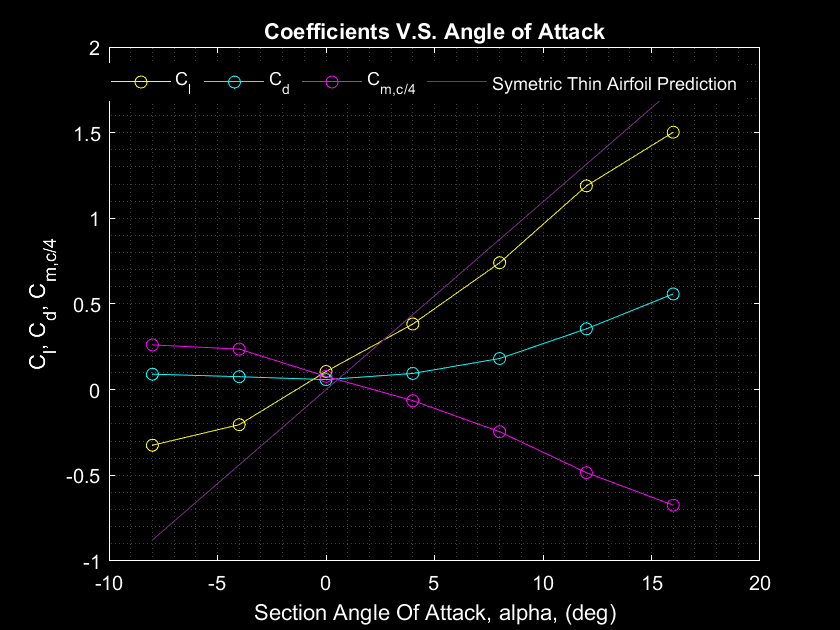


% caclulate free stream velocity for each trial as a function of the heads
vInfinity = sqrt(2 * rhoLiquid * g * abs(totalHeads - staticHeads) / rhoAir ); % m/s from bernoullis equation (is it valid? eh)

%caclulate reynolds number from each trial as a function of the heads
Res = rhoAir * vInfinity * c / mu; % from definition of reynolds number

% Make charts for forty-eight distributions of pressure coefficients corresponding to all AoA s. 
% Indicate the Reynolds number of each AoA. 
% Having graphical illustrations would be better, but not mandatory.

figure;
plotScalarVsAoA([AoAs; Cls; Cds; Cmc_4s])

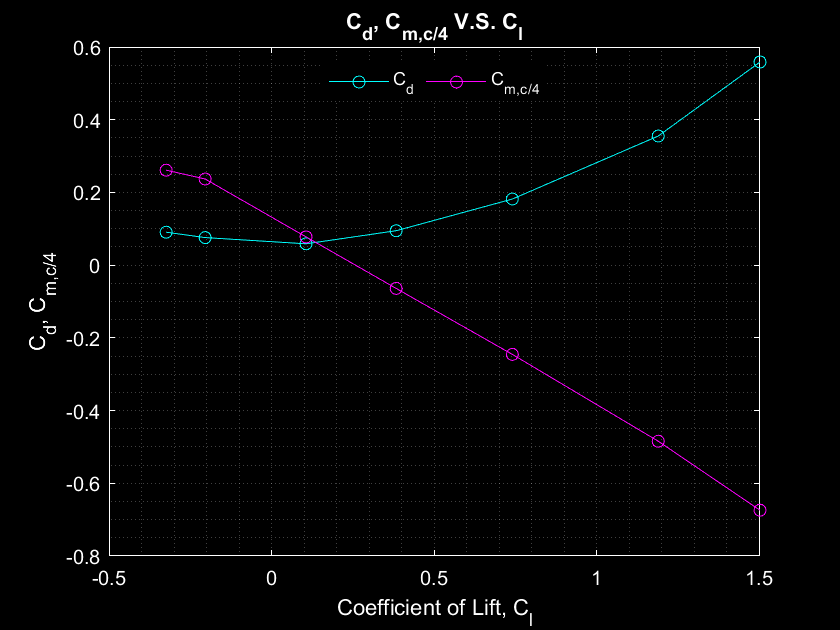

figure;
plotScalarVsCl(Cls, Cds, Cmc_4s)

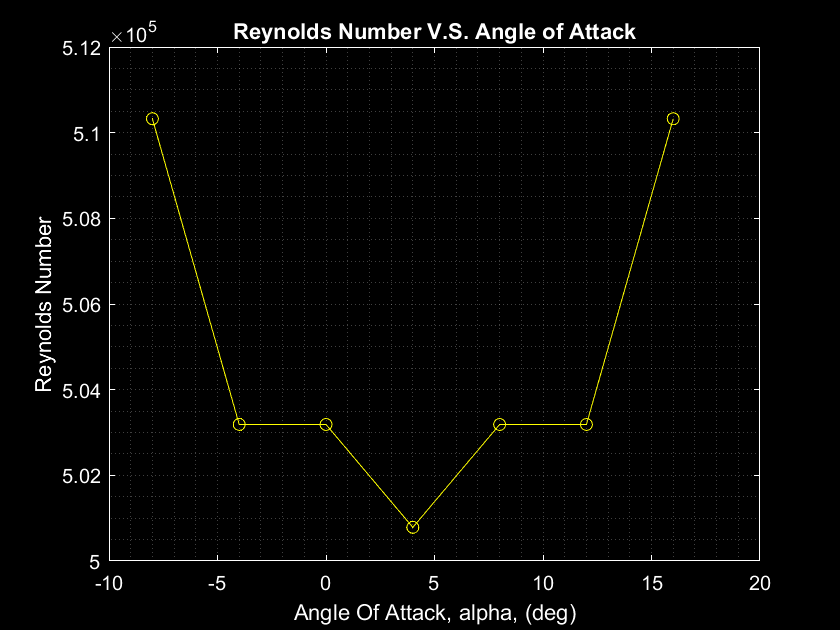

figure;
plotReVsAoa(Res,AoAs)

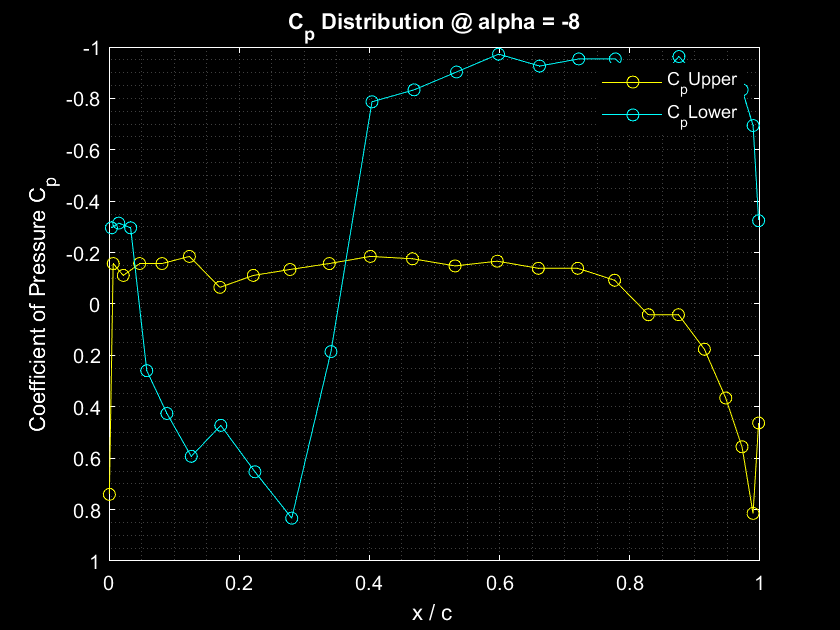

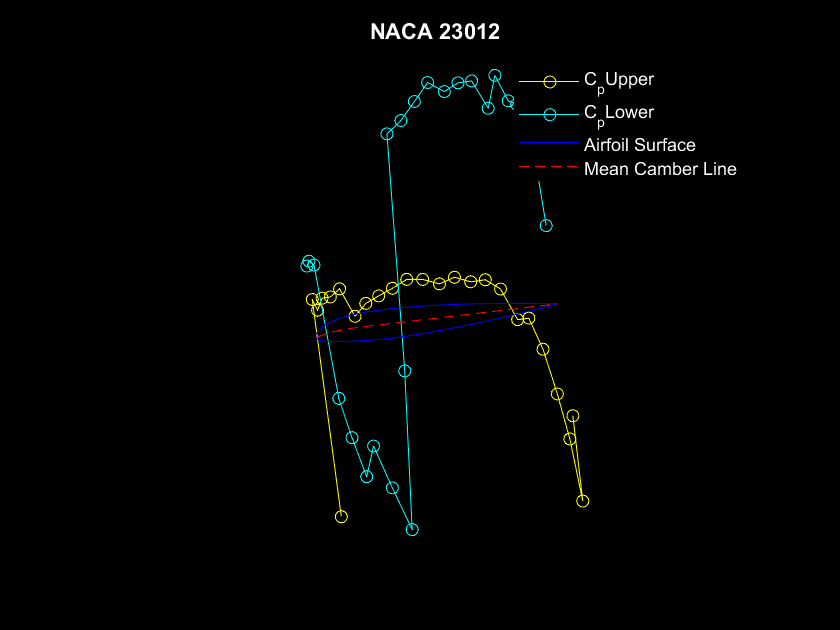

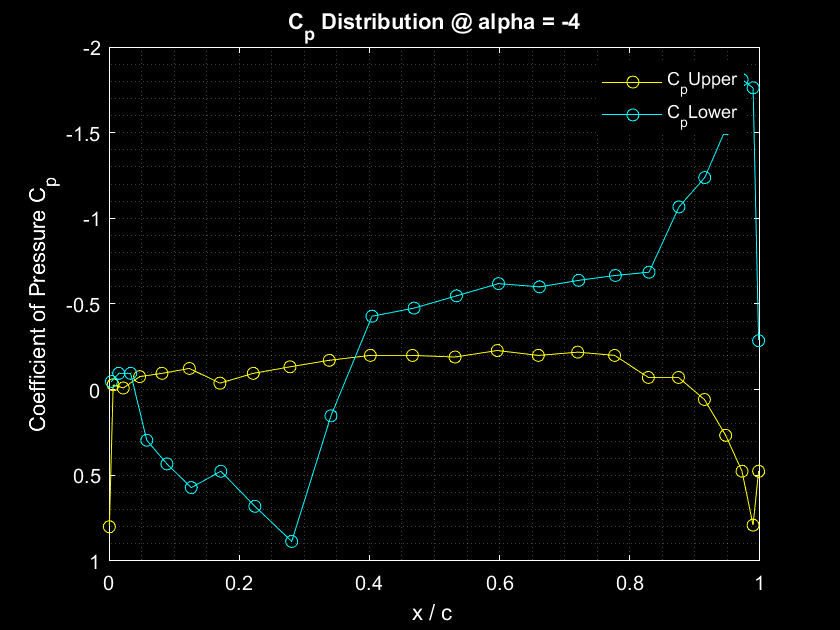

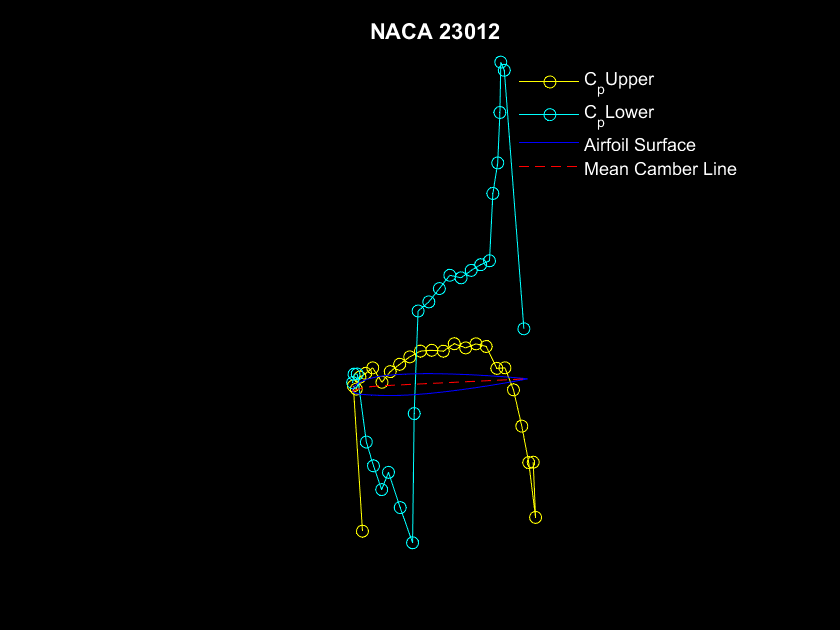

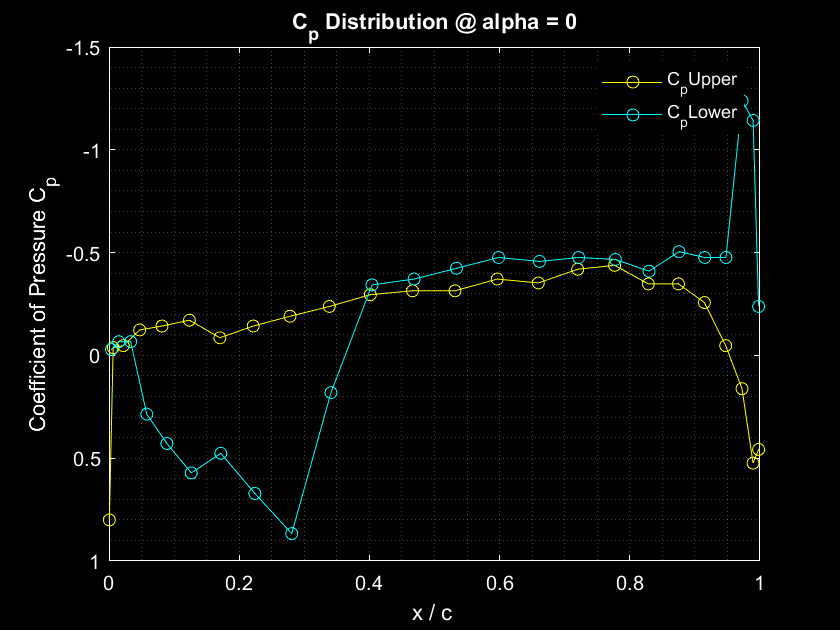

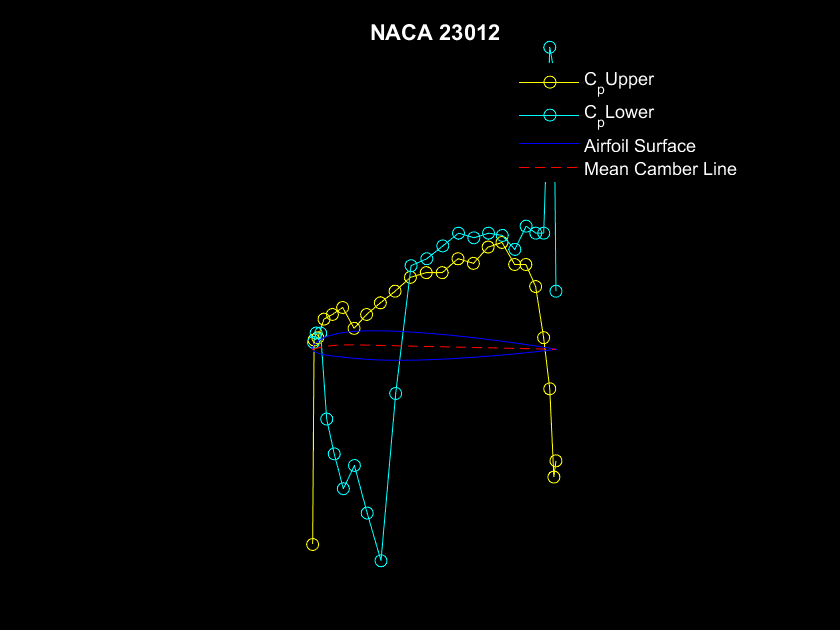

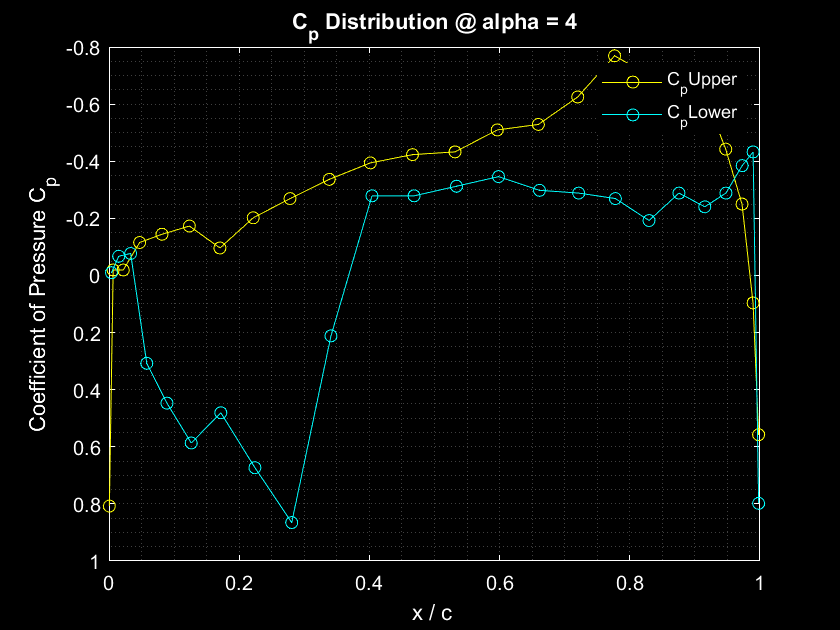

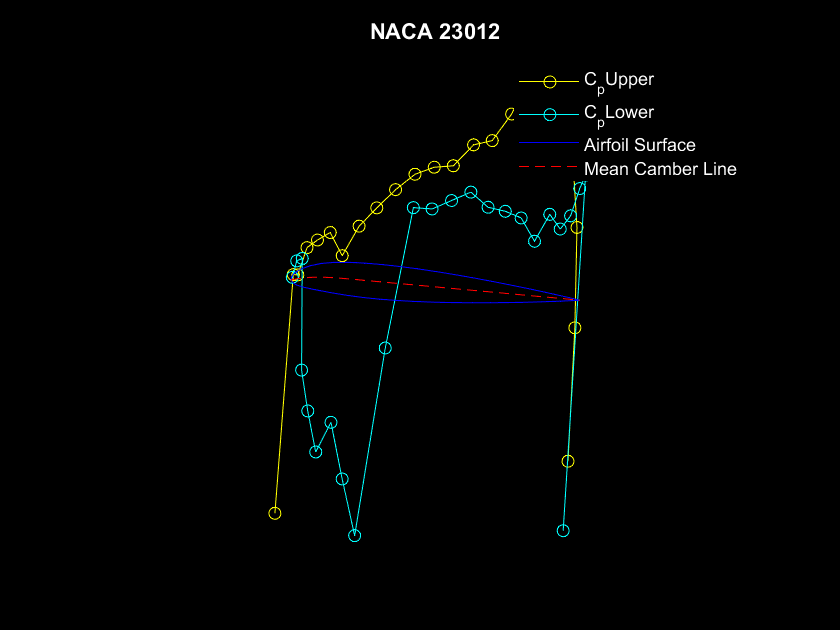


%probably put this inside the loop
for i = 1:countOfAoAs
    figure;
    %dont forget to put Re in these plots
    plotCpDistribution(airfoil,CpUppers(:,i),CpLowers(:,i),AoAs(i))
    figure;
    plotCpDistributionWithAirfoil(airfoil,CpUppers(:,i),CpLowers(:,i),AoAs(i))
end


%Make figures for total coefficients of lift, drag and moment on the quarter chord corresponding to different AoA s, just like Fig.1&2.
% These results should be compared  with theoretical results, which can either be calculated by the classical thin airfoil theory or extracted from Fig.1 & 2


function Re = reynoldsNumber(v)
    mu = 1.78E-5; % kg/(m*s)
    rho = 1.225; % kg/m^3
    c = .195; % m
    Re = rho * v * c / mu;
end

function vInf = velocityInf(ht,hs)
    rhoAir = 1.225; % kg/m^3
    rhoLiquid = 826; % kg/m^3
    g = 9.81; % m/s^2
    vInf = sqrt(2 * rhoLiquid * g * abs(ht-hs) / rhoAir); % m/s
end

function airfoil = loadAirfoil()
    iaf.designation='23012';
    iaf.n=24;
    iaf.HalfCosineSpacing=1;
    iaf.wantFile=1;
    iaf.datFilePath='./'; % Current folder
    iaf.is_finiteTE=0;
    airfoil = naca5gen(iaf);
end

function [DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c] = possitionDeltas(airfoil)
        xLower_c = (airfoil.xL(1:end-1) + airfoil.xL(2:end)) / 2;
        xUpper_c = (airfoil.xU(1:end-1) + airfoil.xU(2:end)) / 2; 
        yLower_c = (airfoil.zL(1:end-1) + airfoil.zL(2:end)) / 2;
        yUpper_c = (airfoil.zU(1:end-1) + airfoil.zU(2:end)) / 2;
        
        DxLower_c = airfoil.xL(2:end) - airfoil.xL(1:end-1);
        DxUpper_c = airfoil.xU(1:end-1) - airfoil.xU(2:end);
        DyLower_c = airfoil.zL(2:end) - airfoil.zL(1:end-1);
        DyUpper_c = airfoil.zU(1:end-1) - airfoil.zU(2:end);
end

function cp = getCp(hs, ht, h)
    cp = (h-hs)./(ht-hs);
end

function [CpUpper, CpLower] = getCps(hs, ht, hlocal)
    hUpper = hlocal(1:end/2);
    hLower = hlocal(end/2+1:end);
    CpUpper = getCp(hs, ht, hUpper);
    CpLower = getCp(hs, ht, hLower);
end


function [Cn, Ca, CmLe] = coefficientsOfForce(CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c)
    Cn = sum(CpLower .* DxLower_c) - sum(CpUpper .* DxUpper_c) ;
%    Ca = sum(CpLower) * sum(DyLower_c) - sum(CpUpper) * sum(DyUpper_c); %this one was commented out this morning
    Ca =  sum(CpUpper .* DyUpper_c) - sum(CpLower .* DyLower_c);
    CmLe = sum(CpUpper .* DxUpper_c .* xUpper_c) - sum(CpLower .* DxLower_c .* xLower_c) + sum(CpUpper .* DyUpper_c .* yUpper_c) - sum(CpLower .* DyLower_c .* yLower_c);
end

function [Cl, Cd, CmC_4] = coefficientsOfAerodynamicForces(alpha, CoefForce)
    Cn = CoefForce(1);
    Ca = CoefForce(2);
    CmLe = CoefForce(3);
    Cl = Cn * cosd(alpha) - Ca * sind(alpha);
    Cd = Cn * sind(alpha) + Ca * cosd(alpha);
    CmC_4 = CmLe + Cl / 4;
end

function [Cl, Cd, CmC_4] = getCoeffs(alpha, CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c)
    [Cn, Ca, CmLe] = coefficientsOfForce(CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c);
    CoefForce = [Cn, Ca, CmLe];
    [Cl, Cd, CmC_4] = coefficientsOfAerodynamicForces(alpha, CoefForce);
end

function plotAirfoil(airfoil,alpha)
    % TODO: consider implementing alpha later
    % for alpha we want to move airfoil to center of rotation, rotate and
    % then translate it back
    % TODO: mayby implement alpha by passing a transformation matrix
    x = airfoil.x; z = airfoil.z;
    xU = airfoil.xU; zU = airfoil.zU;
    xL = airfoil.xL; zL = airfoil.zL;
    xC = airfoil.xC; zC = airfoil.zC;
    name = airfoil.name;
    
       
    hold on;
    airfoilPlot(1) = plot(x,z,'b-');
    set(airfoilPlot(1),'DisplayName','Airfoil Surface');
%     plot(xU,zU,'bo-')
%     plot(xL,zL,'ro-')

    airfoilPlot(2) = plot(xC,zC,'r--');
    set(airfoilPlot(2),'DisplayName','Mean Camber Line');

    title(name)
end

function plotCpDistribution(airfoil,CpUpper,CpLower,alpha)
    x = airfoil.x; z = airfoil.z;
    xU = airfoil.xU; zU = airfoil.zU;
    xL = airfoil.xL; zL = airfoil.zL;
    xC = airfoil.xC; zC = airfoil.zC;
    
    xLower_c = (airfoil.xL(1:end-1) + airfoil.xL(2:end)) / 2;
    xUpper_c = (airfoil.xU(1:end-1) + airfoil.xU(2:end)) / 2; 
    yLower_c = (airfoil.zL(1:end-1) + airfoil.zL(2:end)) / 2;
    yUpper_c = (airfoil.zU(1:end-1) + airfoil.zU(2:end)) / 2;
    
    %consider plotting lift at that cord value as well
    % calculate pressure sensor locations
    xUs = (xU(1:end-1) + xU(2:end)) / 2;
    xLs = (xL(1:end-1) + xL(2:end)) / 2;
    
%     plot1(1) = plot(xUs,CpUpper,'yo-'); hold on;
%     plot1(2) = plot(xLs,CpLower,'co-'); hold on;
    plot1(1) = plot(xUpper_c,CpUpper,'yo-'); hold on;
    plot1(2) = plot(xLower_c,CpLower,'co-'); hold on;
    
    
    set(plot1(1),'DisplayName','C_pUpper','Color',[1 1 0]); set(plot1(2),'DisplayName','C_pLower','Color',[0 1 1]);
    set(gca,'YDir','reverse'); %reversed because it makes sense as up and down pressures
    
    title(sprintf("C_p Distribution @ alpha = %g", alpha),"Color",'w'); xlabel('x / c ','Color','w'); ylabel('Coefficient of Pressure C_p','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','vertical','Location','northeast','EdgeColor','none');
    
end

function plotCpDistributionWithAirfoil(airfoil,CpUpper,CpLower,alpha)
    x = airfoil.x; z = airfoil.z;
    xU = airfoil.xU; zU = airfoil.zU;
    xL = airfoil.xL; zL = airfoil.zL;
    xC = airfoil.xC; zC = airfoil.zC;
    
    %consider plotting lift at that cord value as well
    % calculate pressure sensor locations
    xUs = (xU(1:end-1) + xU(2:end)) / 2;
    xLs = (xL(1:end-1) + xL(2:end)) / 2;
    
    zUs = (zU(1:end-1) + zU(2:end)) / 2;
    zLs = (zL(1:end-1) + zL(2:end)) / 2;
    
%     plot1(1) = plot(xUs,-CpUpper + zUs,'yo-'); hold on;
%     plot1(2) = plot(xLs,-CpLower + zUs,'co-'); hold on;
    plot1(1) = plot(xUs,-CpUpper,'yo-'); hold on;
    plot1(2) = plot(xLs,-CpLower,'co-'); hold on;
    
    set(plot1(1),'DisplayName','C_pUpper','Color',[1 1 0]); set(plot1(2),'DisplayName','C_pLower','Color',[0 1 1]);
    %set(gca,'YDir','reverse');
    
    title(sprintf("C_p Distribution With airfoil @ alpha = %g", alpha),"Color",'w'); xlabel('x / c ','Color','w'); ylabel('Coefficient of Pressure C_p','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','vertical','Location','northeast','EdgeColor','none');
    
    hold on
    plotAirfoil(airfoil,alpha)
    axis equal
    
    camroll(-alpha)
    hold on
    axis off
    
end

function plotReVsAoa(Re,AoA)
    plot1 = plot(AoA,Re,'wo-'); hold on;
    title("Reynolds Number V.S. Angle of Attack","Color",'w'); xlabel('Angle Of Attack, alpha, (deg)','Color','w'); ylabel('Reynolds Number','Color','w');
    set(plot1,'DisplayName','Reynolds Number','Color',[1 1 0]);
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
end

function plotScalarVsAoA(scalars)
    AoA = scalars(1,:);
    %Re = scalars(2,:); %Re is aprox const
    Cl = scalars(2,:);
    Cd = scalars(3,:);
    Cmc_4 = scalars(4,:);
    
    plot1(1) = plot(AoA,Cl,'yo-'); hold on;
    plot1(2) = plot(AoA,Cd,'co-'); hold on;
    plot1(3) = plot(AoA,Cmc_4,'magentao-'); hold on;
    plot1(4) = plot(AoA, 2*pi*deg2rad(AoA));
    
    set(plot1(1),'DisplayName','C_l','Color',[1 1 0]); set(plot1(2),'DisplayName','C_d','Color',[0 1 1]); set(plot1(3),'DisplayName','C_m_,_c_/_4','Color',[1 0 1]); set(plot1(4),'DisplayName','Symetric Thin Airfoil Prediction');
    
    title("Coefficients V.S. Angle of Attack","Color",'w'); xlabel('Section Angle Of Attack, alpha, (deg)','Color','w'); ylabel('C_l, C_d, C_m_,_c_/_4','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','horizontal','Location','north','EdgeColor','none');
end

function plotScalarVsCl(Cl,Cd,Cmc_4)
    %Re = scalars(2,:); %Re is aprox const
%     Cl = scalars(1,:);
%     Cd = scalars(2,:);
%     Cmc_4 = scalars(3,:);
    
    plot1(1) = plot(Cl,Cd,'co-'); hold on;
    plot1(2) = plot(Cl,Cmc_4,'magentao-'); hold on;
    
    set(plot1(1),'DisplayName','C_d','Color',[0 1 1]); 
    set(plot1(2),'DisplayName','C_m_,_c_/_4','Color',[1 0 1]);
    
    title("C_d, C_m_,_c_/_4 V.S. C_l","Color",'w'); xlabel('Coefficient of Lift, C_l','Color','w'); ylabel('C_d, C_m_,_c_/_4','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','horizontal','Location','north','EdgeColor','none');
end
